# 9.evaluateHeatFlux

[`[qx,qy] = evaluateHeatFlux(thermalresults,xq,yq)`](https://ww2.mathworks.cn/help/pde/ug/pde.steadystatethermalresults.evaluateheatflux.html#d120e38675)`：`在`xq`和中指定的二维点处返回热问题的热通量 `yq`。该语法对于稳态和瞬态热模型均有效。

[`[qx,qy,qz] = evaluateHeatFlux(thermalresults,xq,yq,zq)`](https://ww2.mathworks.cn/help/pde/ug/pde.steadystatethermalresults.evaluateheatflux.html#d120e38702)`：`在返回中所指定的3-d点的热问题的热通量 `xq`，`yq`和`zq`。该语法对于稳态和瞬态热模型均有效。

[`[``___``] = evaluateHeatFlux(thermalresults,querypoints)`](https://ww2.mathworks.cn/help/pde/ug/pde.steadystatethermalresults.evaluateheatflux.html#d120e38736)`：`在中指定的2-D或3-D点处返回热问题的热通量`querypoints`。该语法对于稳态和瞬态热模型均有效。

[`[``___``] = evaluateHeatFlux(``___``,iT)`](https://ww2.mathworks.cn/help/pde/ug/pde.steadystatethermalresults.evaluateheatflux.html#d120e38761)`：` 在中指定的时间返回热问题的热通量 `iT`。

[`[qx,qy] = evaluateHeatFlux(thermalresults)`](https://ww2.mathworks.cn/help/pde/ug/pde.steadystatethermalresults.evaluateheatflux.html#d120e38797)

[`[qx,qy,qz] = evaluateHeatFlux(thermalresults)`](https://ww2.mathworks.cn/help/pde/ug/pde.steadystatethermalresults.evaluateheatflux.html#d120e38822)

**二维稳态热模型的热通量**

% thermalmodel = createpde('thermal');
% R1 = [3,4,-1,1,1,-1,1,1,-1,-1]';
% g = decsg(R1,'R1',('R1')');
% geometryFromEdges(thermalmodel,g);
% pdegplot(thermalmodel,'EdgeLabels','on')
% xlim([-1.5 1.5])
% axis equal
% thermalProperties(thermalmodel,'ThermalConductivity',79.5,'Face',1);
% thermalBC(thermalmodel,'Edge',3,'Temperature',500);
% thermalBC(thermalmodel,'Edge',1,'HeatFlux',0);
% thermalBC(thermalmodel,'Edge',[2 4], ...
%                        'ConvectionCoefficient',25, ...
%                        'AmbientTemperature',50);
% generateMesh(thermalmodel);
% results = solve(thermalmodel)
% [qx,qy] = evaluateHeatFlux(results);
% 
% figure
% pdeplot(thermalmodel,'FlowData',[qx qy])

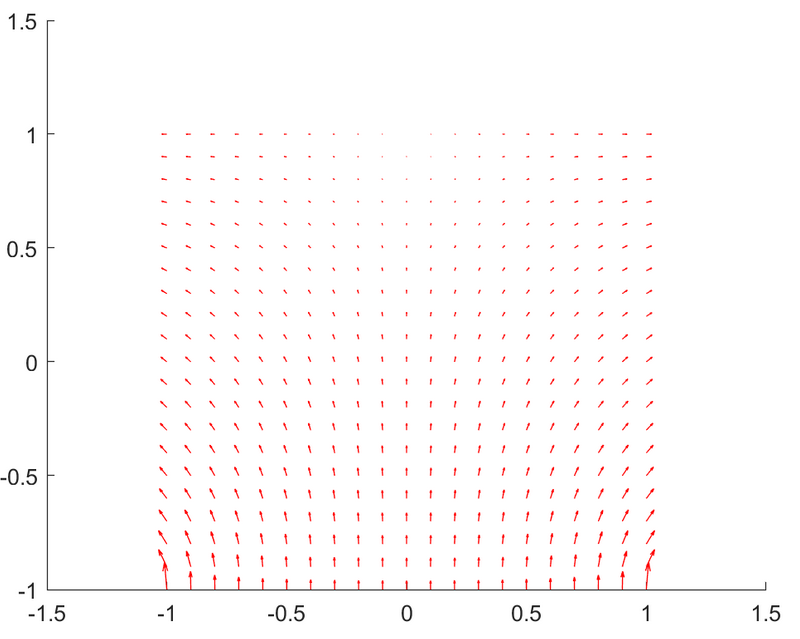

Create a grid specified by `x` and `y` coordinates, and evaluate heat flux to the grid.

% v = linspace(-0.5,0.5,11);
% [X,Y] = meshgrid(v);
% 
% [qx,qy] = evaluateHeatFlux(results,X,Y);

Reshape the `qTx` and `qTy` vectors, and plot the resulting heat flux.

% qx = reshape(qx,size(X));
% qy = reshape(qy,size(Y));
% figure
% quiver(X,Y,qx,qy)

**Heat Flux for 3-D Steady-State Thermal Model**

% thermalmodel = createpde('thermal');
% importGeometry(thermalmodel,'Block.stl'); 
% pdegplot(thermalmodel,'FaceLabels','on','FaceAlpha',0.5)
% title('Copper block, cm')
% axis equal
% thermalmodel = createpde('thermal');
% importGeometry(thermalmodel,'C:\Users\ZGY\Desktop\structure_heat_matlab\11.stl'); 
% pdegplot(thermalmodel,'FaceLabel','on','FaceAlpha',0.5)
% title('Copper block, cm')
% axis equal
% thermalProperties(thermalmodel,'ThermalConductivity',4);
% thermalBC(thermalmodel,'Face',4,'Temperature',373);
% thermalBC(thermalmodel,'Face',5,'Temperature',573);
% thermalBC(thermalmodel,'Face',2,'HeatFlux',-20);
% generateMesh(thermalmodel);
% thermalresults = solve(thermalmodel)
% [qx,qy,qz] = evaluateHeatFlux(thermalresults);
% 
% figure
% pdeplot3D(thermalmodel,'FlowData',[qx qy qz])

Create a grid specified by `x`, `y`, and `z` coordinates, and evaluate heat flux to the grid.

% [X,Y,Z] = meshgrid(-20:0.6:20,-20:0.6:20,0:0.6:40);
% 
% [qx,qy,qz] = evaluateHeatFlux(thermalresults,X,Y,Z);
% qx = reshape(qx,size(X));
% qy = reshape(qy,size(Y));
% qz = reshape(qz,size(Z));
% figure
% quiver3(X,Y,Z,qx,qy,qz)

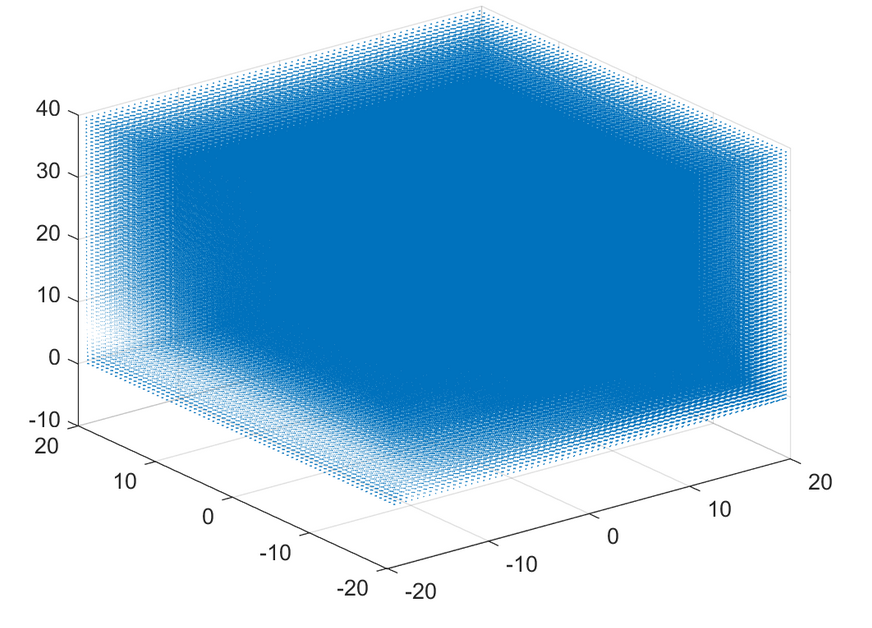

**Heat Flux for Transient Thermal Model on Square**

% thermalmodel = createpde('thermal','transient');
% g = @squareg;
% geometryFromEdges(thermalmodel,g);
% pdegplot(thermalmodel,'EdgeLabels','on')
% xlim([-1.2 1.2])
% ylim([-1.2 1.2])
% axis equal
% thermalProperties(thermalmodel,'ThermalConductivity',100, ...
%                                'MassDensity',7800, ...
%                                'SpecificHeat',500);
% thermalBC(thermalmodel,'Edge',[1 3 4],'HeatFlux',0);
% thermalBC(thermalmodel,'Edge',2,...
%                        'ConvectionCoefficient',5000, ...
%                        'AmbientTemperature',25);
% thermalIC(thermalmodel,25);
% thermalIC(thermalmodel,100,'Edge',1);
% generateMesh(thermalmodel);
% tlist = 0:1000:200000;
% thermalresults = solve(thermalmodel,tlist)
% v = linspace(-1,1,11);
% [X,Y] = meshgrid(v);
% 
% [qx,qy] = evaluateHeatFlux(thermalresults,X,Y,1:length(tlist));
% tlist(25)
% figure
% quiver(X(:),Y(:),qx(:,25),qy(:,25));
% xlim([-1,1])
% axis equal

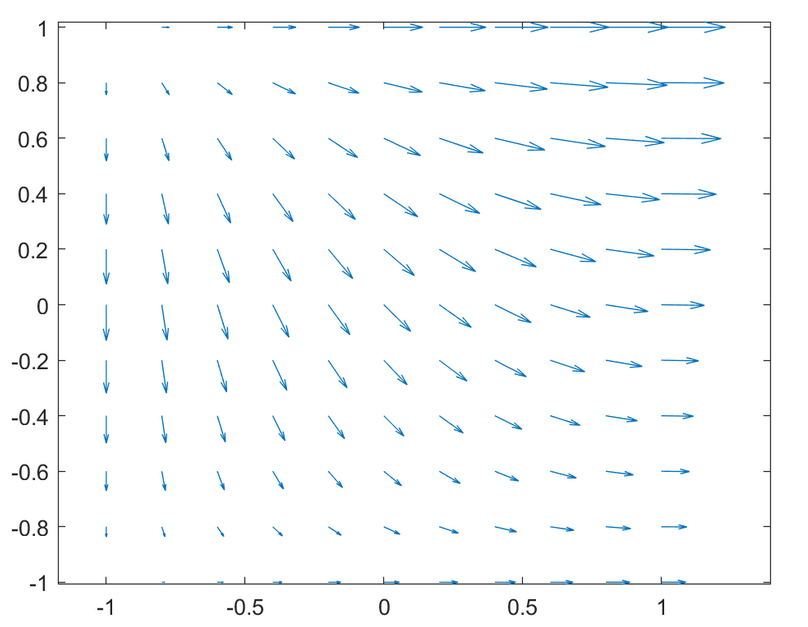

**Heat Flux for Transient Thermal Model on Two Squares Made of Different Materials**

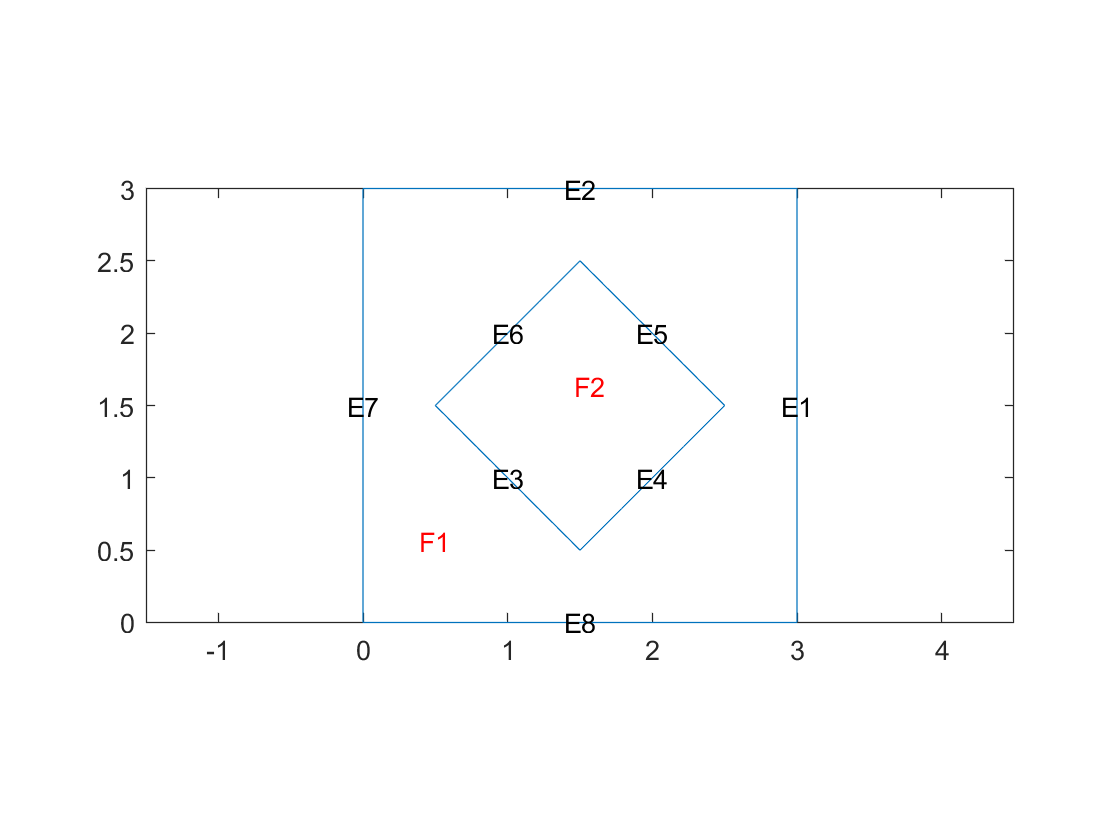

thermalmodel = createpde('thermal','transient');
SQ1 = [3; 4; 0; 3; 3; 0; 0; 0; 3; 3];
D1 = [2; 4; 0.5; 1.5; 2.5; 1.5; 1.5; 0.5; 1.5; 2.5];
gd = [SQ1 D1];
sf = 'SQ1+D1';
ns = char('SQ1','D1');
ns = ns';
dl = decsg(gd,sf,ns);
geometryFromEdges(thermalmodel,dl);
pdegplot(thermalmodel,'EdgeLabels','on','FaceLabels','on')
xlim([-1.5 4.5])
ylim([-0.5 3.5])
axis equal

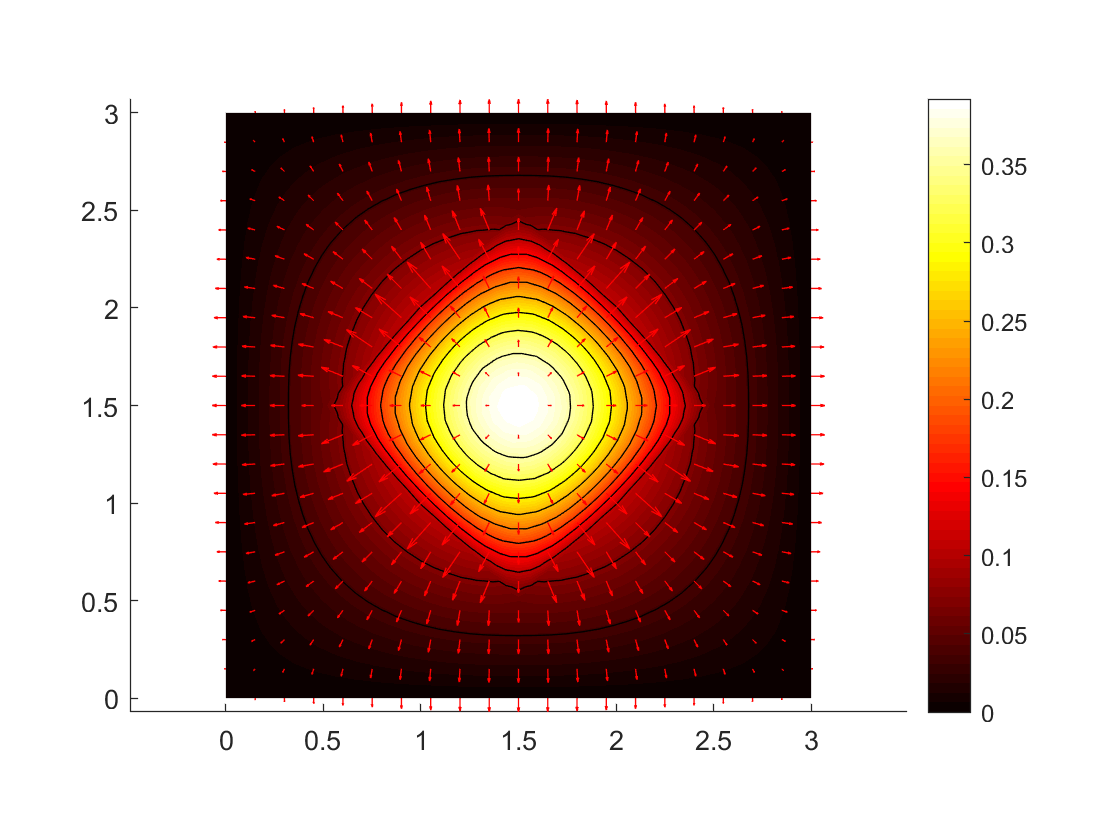

thermalProperties(thermalmodel,'ThermalConductivity',10, ...
                               'MassDensity',2, ...
                               'SpecificHeat',0.1, ...
                               'Face',1);
thermalProperties(thermalmodel,'ThermalConductivity',2, ...
                                'MassDensity',1, ...
                                'SpecificHeat',0.1, ...
                                'Face',2);
internalHeatSource(thermalmodel,4,'Face',2);
thermalBC(thermalmodel,'Temperature',0,'Edge',[1 2 7 8]);
thermalIC(thermalmodel,0);
generateMesh(thermalmodel);
tlist = logspace(-2,-1,10);
thermalresults = solve(thermalmodel,tlist);
temp = thermalresults.Temperature;
[qTx,qTy] = evaluateHeatFlux(thermalresults);

figure
pdeplot(thermalmodel,'XYData',temp(:,10),'Contour','on', ...
                     'FlowData',[qTx(:,10) qTy(:,10)], ...
                     'ColorMap','hot')